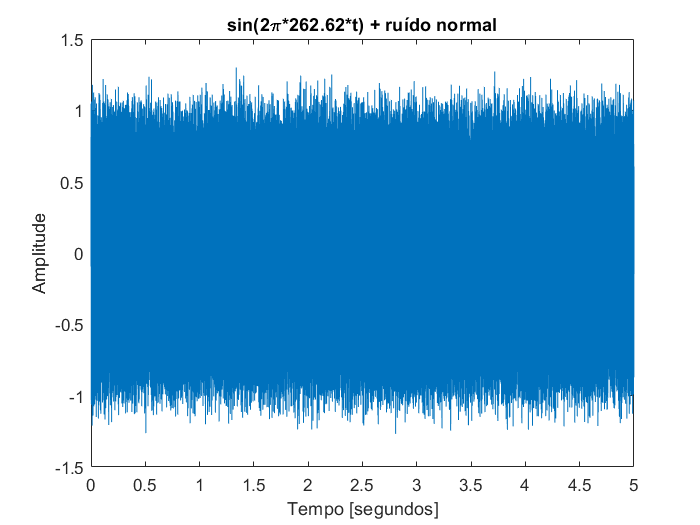

%% UNIVERSIDADE FEDERAL DE VIÇOSA
% ELT - 410 SINAIS E SISTEMAS
% Gabriel Pereira de Calais e Márcio Von Rondow Campos

clc
clear all;
close all;

%% Roteiro Prática 10

%2.1) Exercício 1: Filtro digital passa-baixa 400 Hz

fs = 2000; %Frequência de amostragem
t = 0:1/fs:5; %Vetor tempo
s = sin(2*pi*262.62*t); %Sinal senoidal
n = 0.1*randn(size(s)); %Ruído
sn = s + n; %Sinal senoidal somado ao ruído
figure;
plot(t,sn); title('sin(2\pi*262.62*t) + ruído normal'); xlabel('Tempo [segundos]'); ylabel('Amplitude');

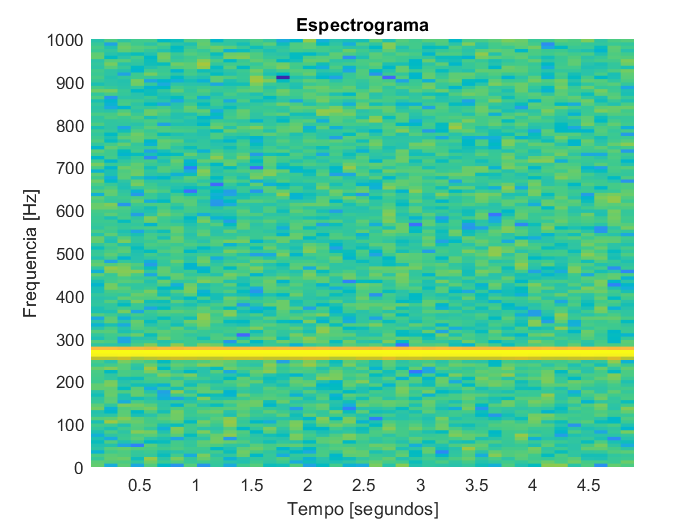


[S,F,T] = spectrogram(sn,256,20,256,fs); %Faz o espectrograma do sinal 7
figure; surf(T,F,10*log10(abs(S)),'EdgeColor','none'); %Plota o espectrograma
axis xy; axis tight; view(0,90);
xlabel('Tempo [segundos]'); ylabel('Frequencia [Hz]'); title('Espectrograma');

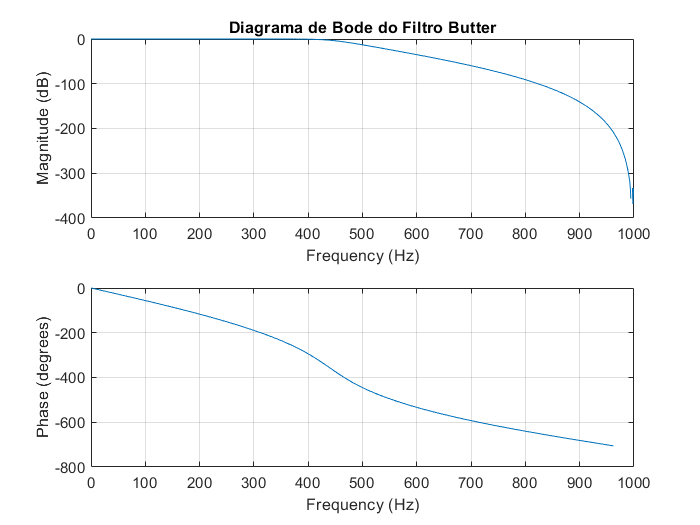


%Filtro Butterworth

[N, Wn] = buttord(400/(fs/2), 600/(fs/2), 1, 35); %Define a ordem do filtro
[B,A] = butter(N,Wn,'low'); %Define os coeficientes e o tipo de filtro
figure; freqz(B,A,1024,fs); title('Diagrama de Bode do Filtro Butter'); %Plota o diagrama de Bode do filtro

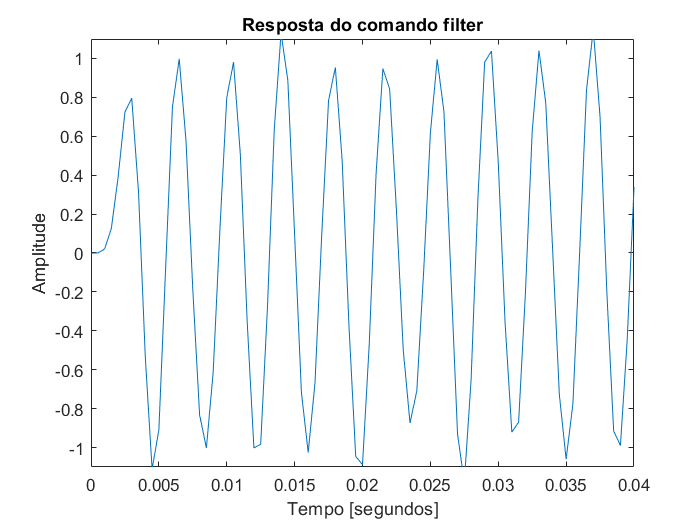


%Filtrando com filter

y = filter(B,A,sn); %Realiza a filtragem
figure; plot(t,y); axis([0 0.04 -1.1 1.1]); xlabel('Tempo [segundos]'); title('Resposta do comando filter'); ylabel('Amplitude');

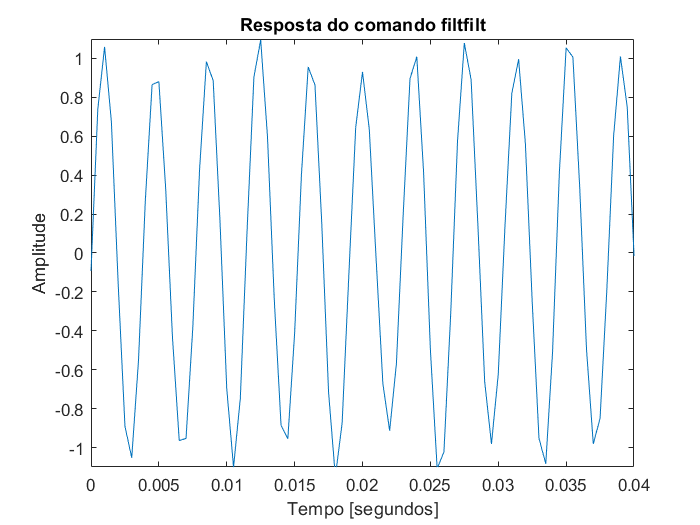

soundsc(y,fs); %Reproduz o som

%Filtrando com filtfilt

y1 = filtfilt(B,A,sn); %Realiza a filtragem com fase zero (indicado para filtros IIR)
figure; plot(t,y1); axis([0 0.04 -1.1 1.1]); xlabel('Tempo [segundos]'); title('Resposta do comando filtfilt'); ylabel('Amplitude');

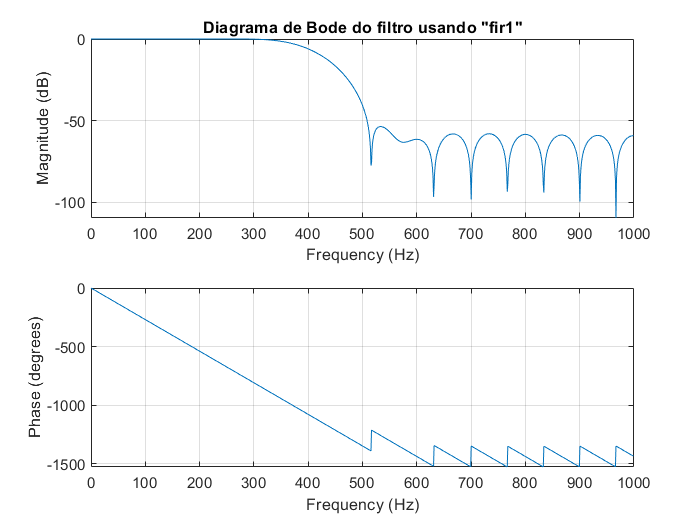

soundsc(y1,fs); %Reproduz o som

%Implementando com fir1

B = fir1(30,400/(fs/2));
freqz(B,1,1024,2000); title('Diagrama de Bode do filtro usando "fir1"'); %Plota o diagrama de Bode do filtro

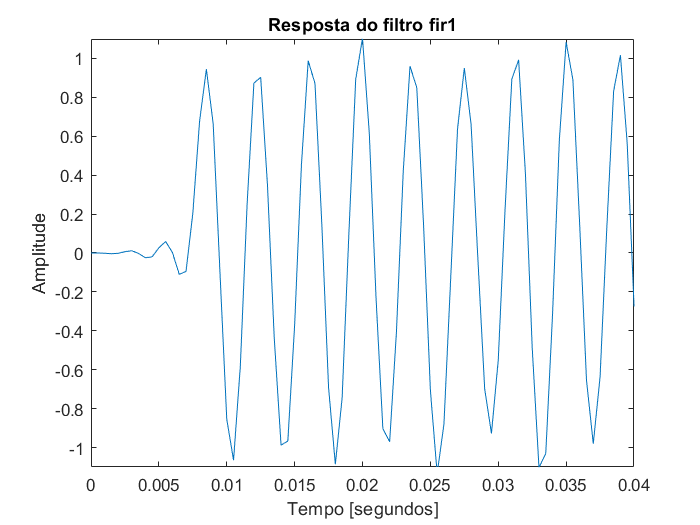

y2 = filter(B,1,sn);
figure; plot(t,y2); axis([0 0.04 -1.1 1.1]); xlabel('Tempo [segundos]'); title('Resposta do filtro fir1'); ylabel('Amplitude');

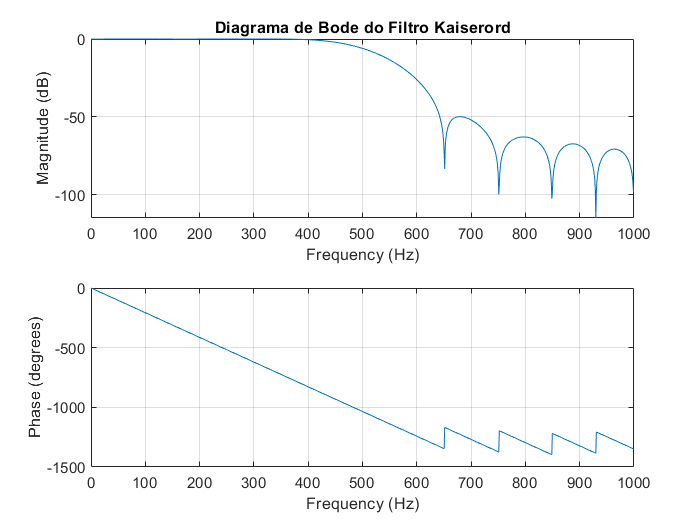

soundsc(y2,fs); %Reproduz o som

%Implementando com kaiserord

[N,Wn,beta,ftype] = kaiserord([400/(fs/2) 600/(fs/2)], [1 0], [0.05 0.01]); %Implementa a ordem o filtro
[B,A] = fir1(N,Wn,'low'); %Define os coeficientes e o tipo de filtro
figure; freqz(B,A,1024,fs); title('Diagrama de Bode do Filtro Kaiserord'); %Plota o diagrama de Bode do filtro

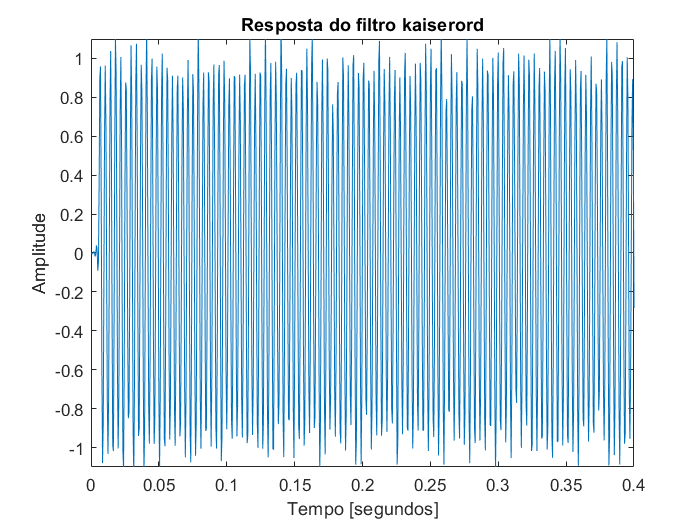

y3 = filter(B,A,sn);
figure; plot(t,y3); axis([0 0.4 -1.1 1.1]); xlabel('Tempo [segundos]'); title('Resposta do filtro Kaiserord'); ylabel('Amplitude');

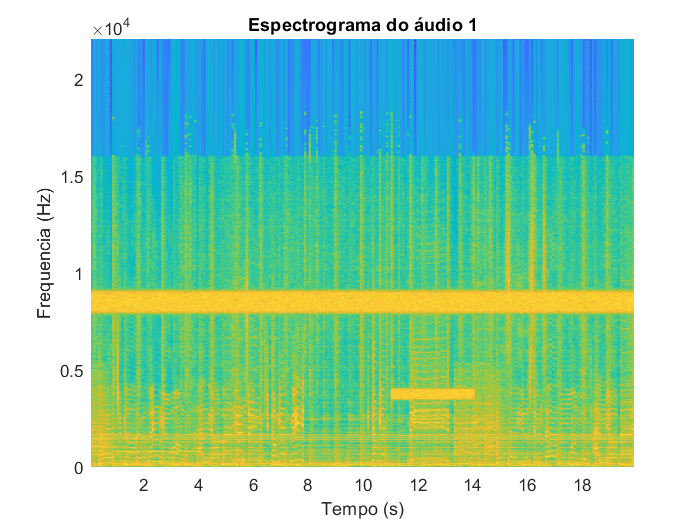


%% 2.2)  Limpeza de áudio

[s1, fs1] = audioread('1.wav'); %Carrega o áudio para a workspace
sound(s1, fs1); %Reproduz o som
t1 = 0:1/fs1:(length(s1)-1)/fs1; %Define o vetor de tempo
[s7, fs7] = audioread('7.wav'); %Carrega o áudio para a workspace
sound(s7, fs7); %Reproduz o som
t7 = 0:1/fs7:(length(s7)-1)/fs7; %Define o vetor de tempo

[S,F,T] = spectrogram(s1,1024*4,4*80,4*1024,fs1); %Faz o espectrograma do sinal 1
figure; surf(T,F,10*log10(abs(S)),'EdgeColor','none'); %Plota o espectrograma
axis xy; axis tight; view(0,90);
xlabel('Tempo (s)'); ylabel('Frequencia (Hz)'); title('Espectrograma do áudio 1');

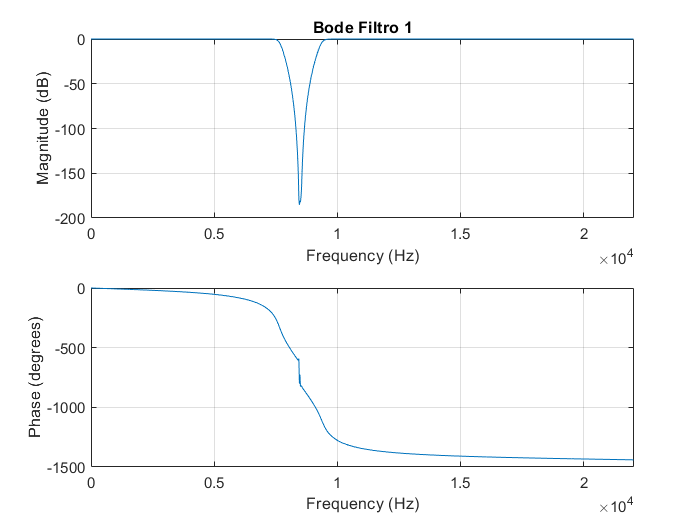


%Filtros Butterworth rejeita faixa de diferentes frequências de corte:
[N, Wn] = buttord([7500/(fs1/2) 9500/(fs1/2)], [8000/(fs1/2) 9000/(fs1/2)], 1, 35);
[B,A] = butter(N,Wn,'stop');
figure; freqz(B,A,1024,fs1); title('Bode Filtro 1');

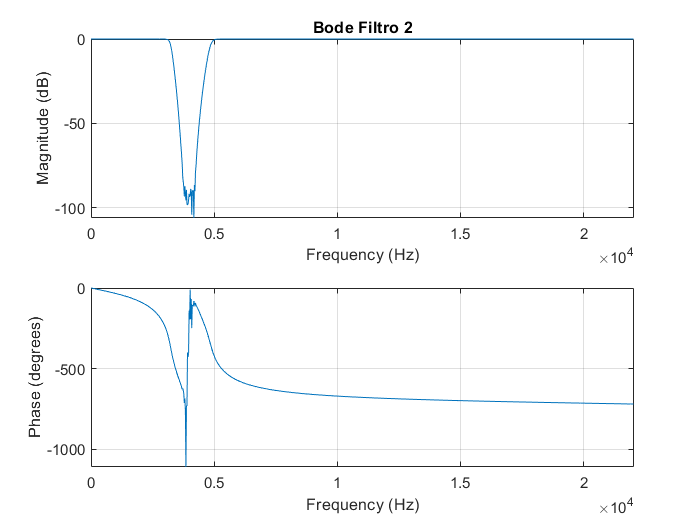

ys1 = filtfilt(B,A,s1); %Realiza a filtragem
[N, Wn] = buttord([3000/(fs1/2) 5000/(fs1/2)], [3500/(fs1/2) 4500/(fs1/2)], 1, 35);
[B,A] = butter(N,Wn,'stop');
figure; freqz(B,A,1024,fs1); title('Bode Filtro 2');

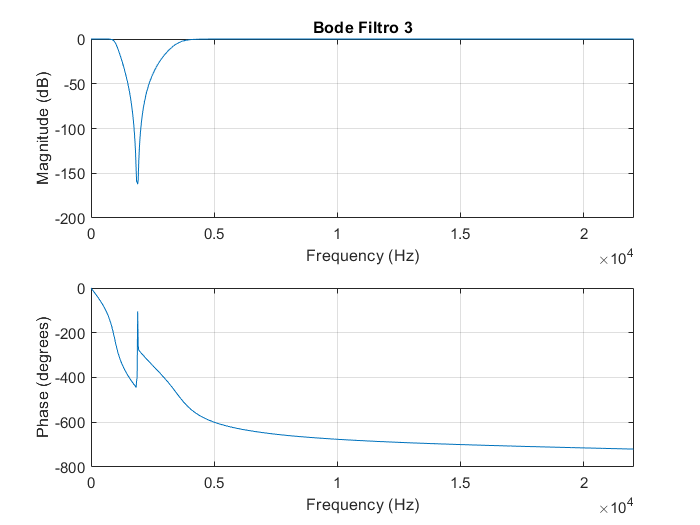

ys2 = filtfilt(B,A,ys1); %Realiza a filtragem
[N, Wn] = buttord([500/(fs1/2) 4000/(fs1/2)], [1000/(fs1/2) 3500/(fs1/2)], 1, 5);
[B,A] = butter(N,Wn,'stop');
figure; freqz(B,A,1024,fs1); title('Bode Filtro 3');

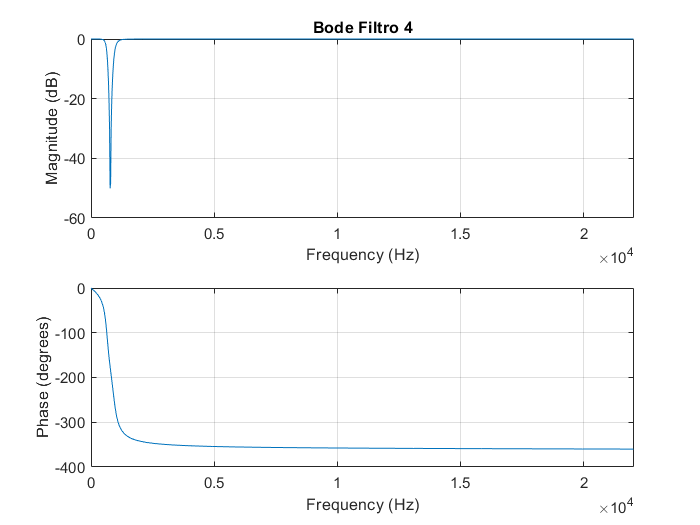

ys3 = filtfilt(B,A,ys2); %Realiza a filtragem
[N, Wn] = buttord([500/(fs1/2) 1100/(fs1/2)], [650/(fs1/2) 950/(fs1/2)], 1, 5);
[B,A] = butter(N,Wn,'stop');
figure; freqz(B,A,1024,fs1); title('Bode Filtro 4');

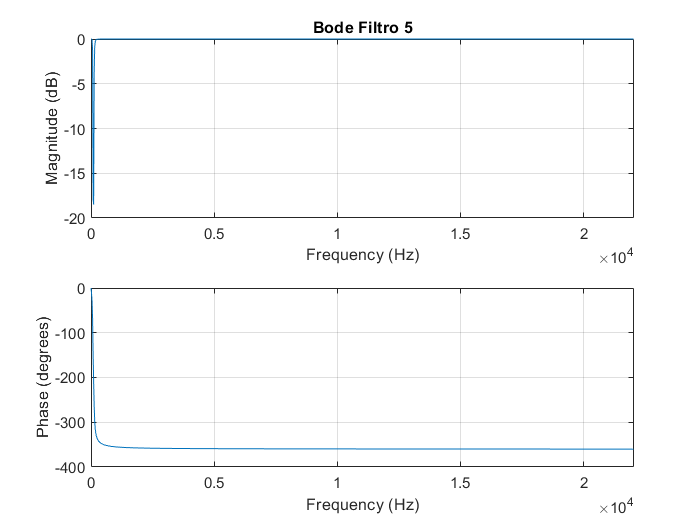

ys4 = filtfilt(B,A,ys3); %Realiza a filtragem
[N, Wn] = buttord([50/(fs1/2) 150/(fs1/2)], [75/(fs1/2) 125/(fs1/2)], 1, 5);
[B,A] = butter(N,Wn,'stop');
figure; freqz(B,A,1024,fs1); title('Bode Filtro 5');

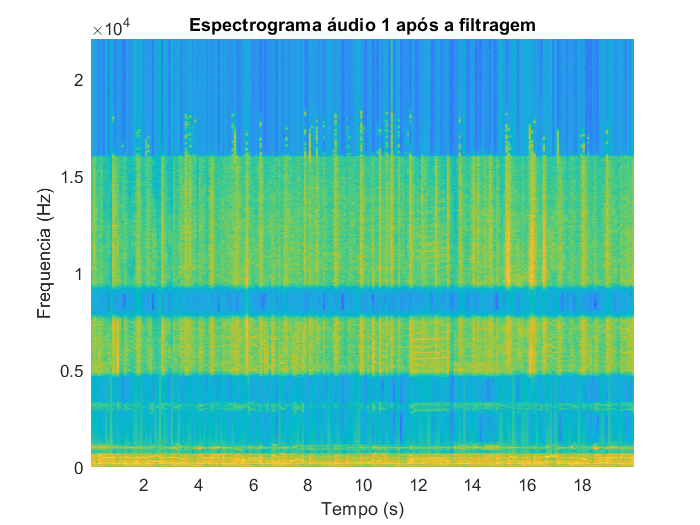

ys5 = filtfilt(B,A,ys4); sound(ys5,fs1); %Realiza a filtragem e reproduz o som final

[S,F,T] = spectrogram(ys5,1024*4,4*80,4*1024,fs1); %Faz o espectrograma do sinal 1
figure; surf(T,F,10*log10(abs(S)),'EdgeColor','none'); %Plota o espectrograma
axis xy; axis tight; view(0,90);
xlabel('Tempo (s)'); ylabel('Frequencia (Hz)'); title('Espectrograma áudio 1 após a filtragem');

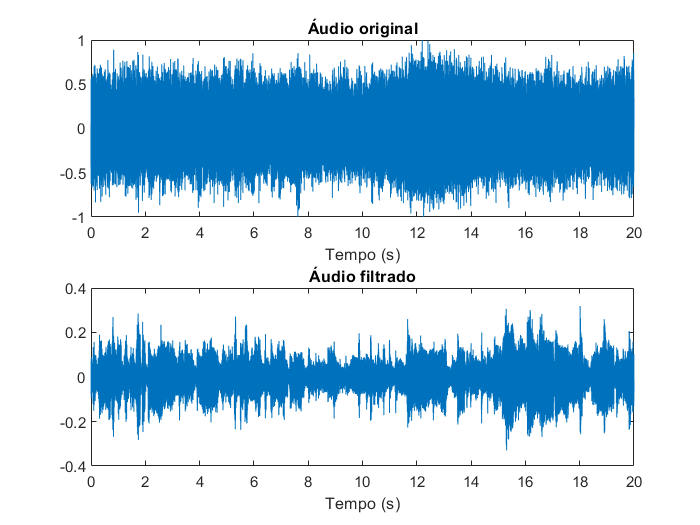


figure; subplot(211); plot(t1,s1); xlabel('Tempo (s)'); title('Áudio original');
subplot(212); plot(t1,ys5); xlabel('Tempo (s)'); title('Áudio filtrado');

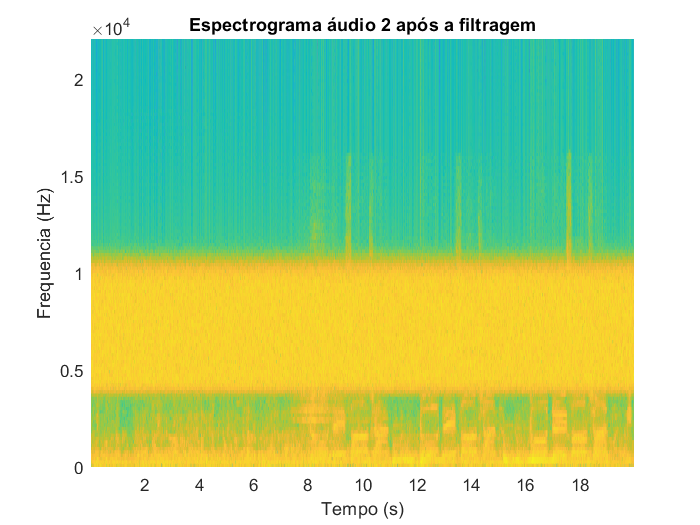


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

[S,F,T] = spectrogram(s7,256,20,256,fs7); %Faz o espectrograma do sinal 7
figure; surf(T,F,10*log10(abs(S)),'EdgeColor','none'); %Plota o espectrograma
axis xy; axis tight; view(0,90);
xlabel('Tempo (s)'); ylabel('Frequencia (Hz)'); title('Espectrograma áudio 2 após a filtragem');

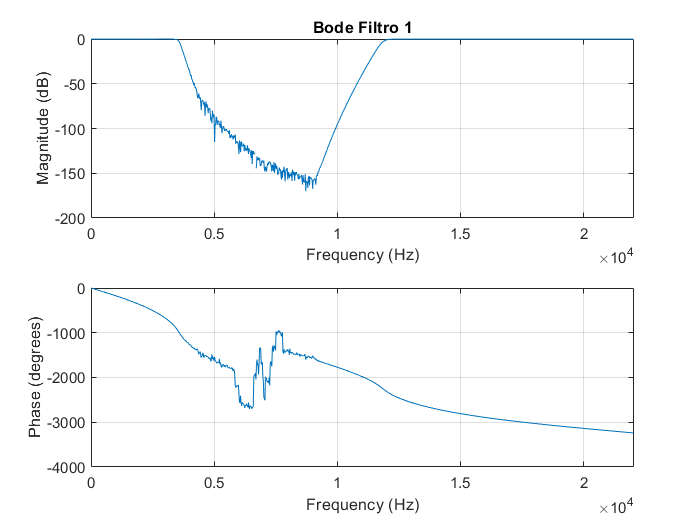


%Filtro Butterworth rejeita faixa
[N, Wn] = buttord([3000/(fs7/2) 12000/(fs7/2)], [3750/(fs7/2) 11500/(fs7/2)], 1, 16);
[B,A] = butter(N,Wn,'stop');
figure; freqz(B,A,1024,fs7); title('Bode Filtro 1');

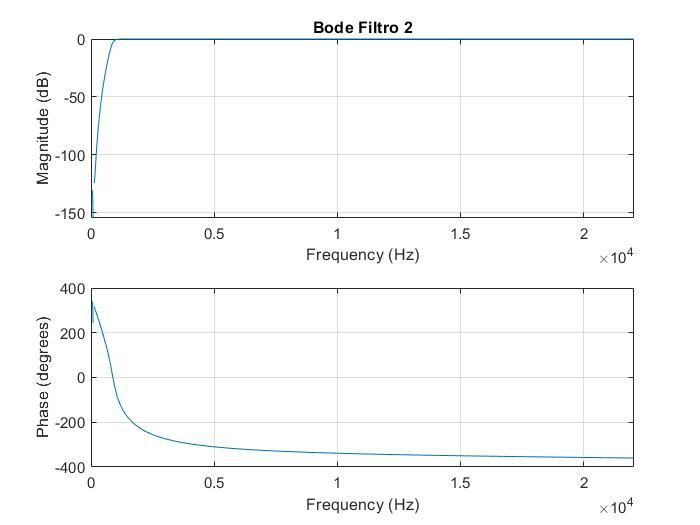

ys7a = filtfilt(B,A,s7); sound(ys7a,fs7);

%Filtro Butterworth passa-altas
[N, Wn] = buttord(1000/(fs7/2), 500/(fs7/2), 1, 40);
[B,A] = butter(N,Wn,'high');
figure; freqz(B,A,1024,fs7); title('Bode Filtro 2');

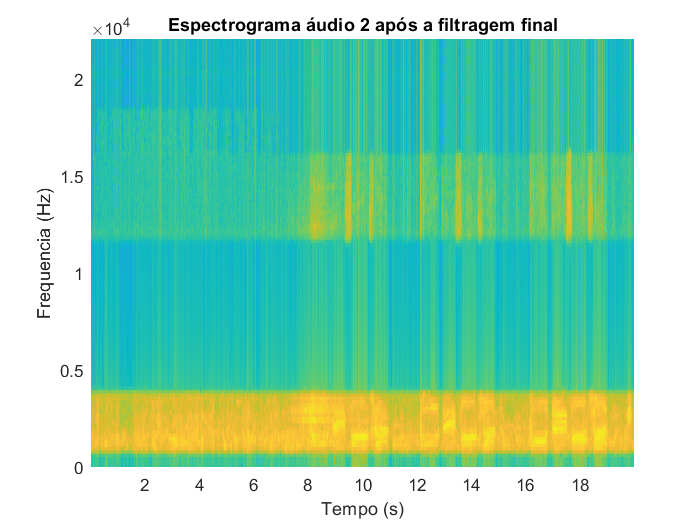

ys7aa = filtfilt(B,A,ys7a); sound(ys7aa,fs7);

[S,F,T] = spectrogram(ys7aa,256,20,256,fs7); %Faz o espectrograma do sinal 7
figure; surf(T,F,10*log10(abs(S)),'EdgeColor','none'); %Plota o espectrograma
axis xy; axis tight; view(0,90);
xlabel('Tempo (s)'); ylabel('Frequencia (Hz)'); title('Espectrograma áudio 2 após a filtragem final');

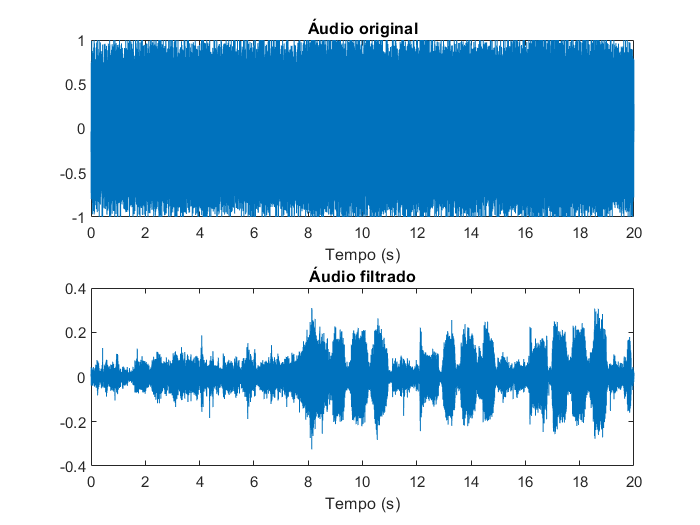


figure; subplot(211); plot(t7,s7); xlabel('Tempo (s)'); title('Áudio original');
subplot(212); plot(t7,ys7aa); xlabel('Tempo (s)'); title('Áudio filtrado');